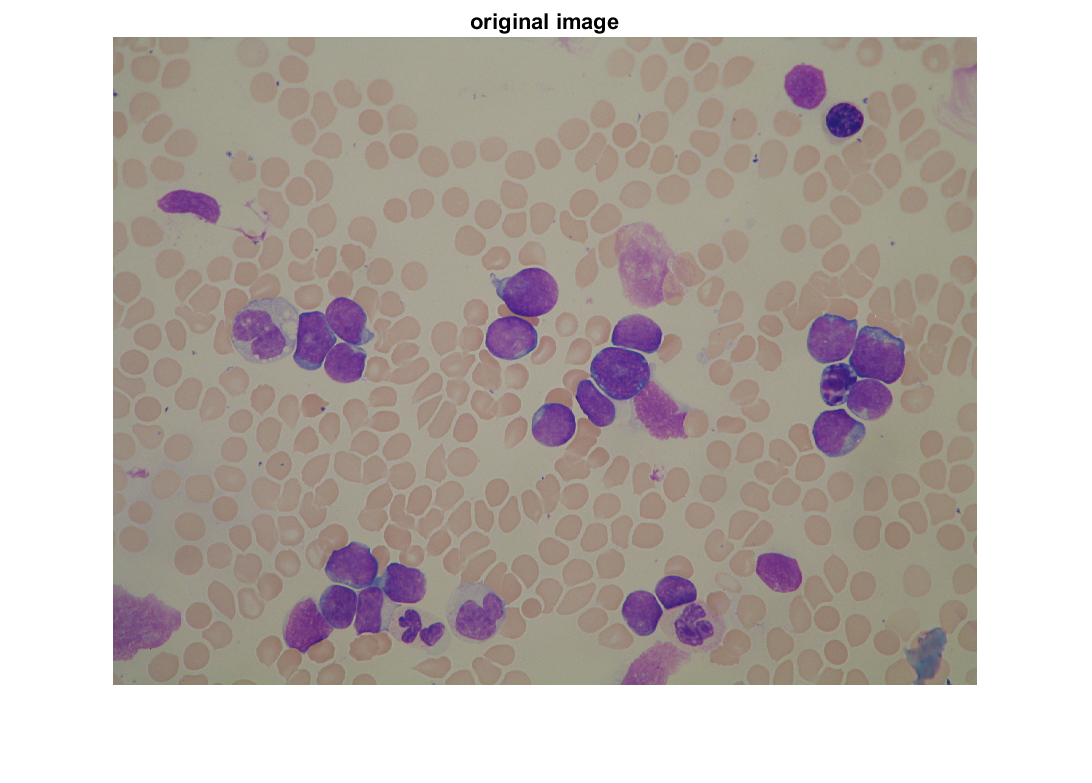

clearvars;
clc;
InputImg = imread('ALL_IDB1\ALL_IDB1\im\Im061_1.jpg');

% separate stains = perform color deconvolution                                  
deconimg = deconv(InputImg);
H=deconimg(:,:,1);
E=deconimg(:,:,2);

[Sh,Hh,Th,Lh]=segmentation(H);
[Se,He,Te,Le]=segmentation(E);

%output
imshow(InputImg);title('original image')

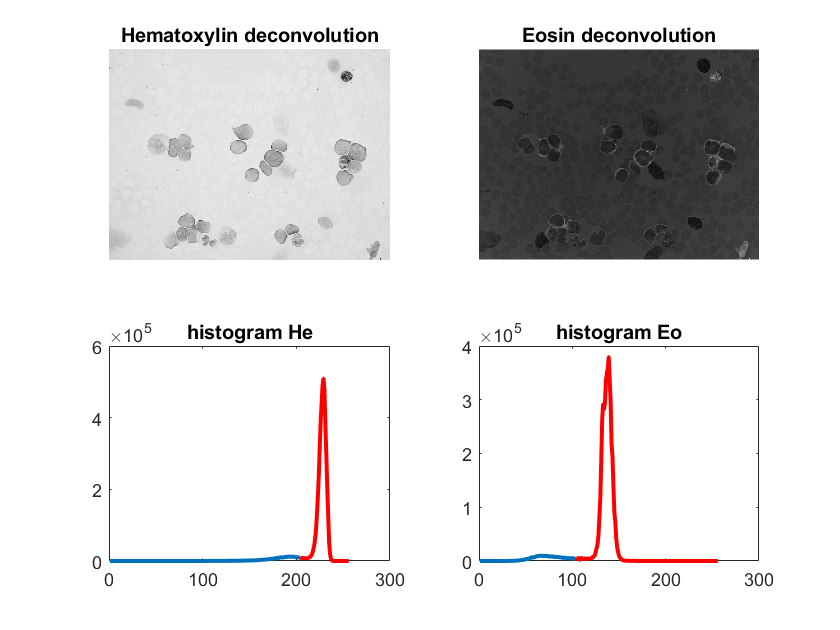

figure();
subplot(221); imshow(H,[]); title('Hematoxylin deconvolution');
subplot(222); imshow(E-H,[]); title('Eosin deconvolution');
subplot(223);plot((1:Th),Hh(1:Th),(Th:Lh),Hh(Th:Lh),'red',"LineWidth",2);title('histogram He')
subplot(224);plot((1:Te),He(1:Te),(Te:Le),He(Te:Le),'red',"LineWidth",2);title('histogram Eo')

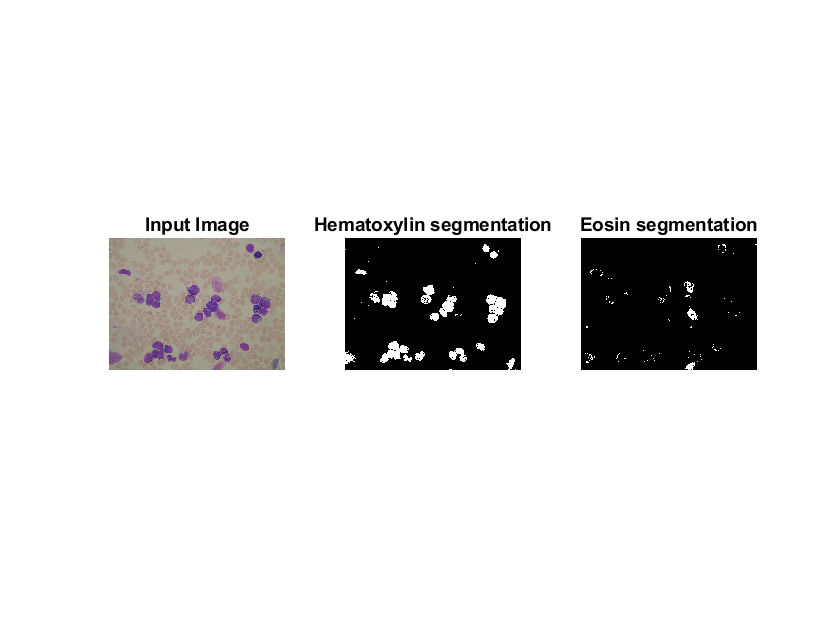

figure;
subplot(131); imshow(InputImg,[]); title('Input Image');
subplot(132); imshow(uint8(Sh),[]); title('Hematoxylin segmentation');
subplot(133); imshow(uint8(Se-Sh),[]); title('Eosin segmentation');

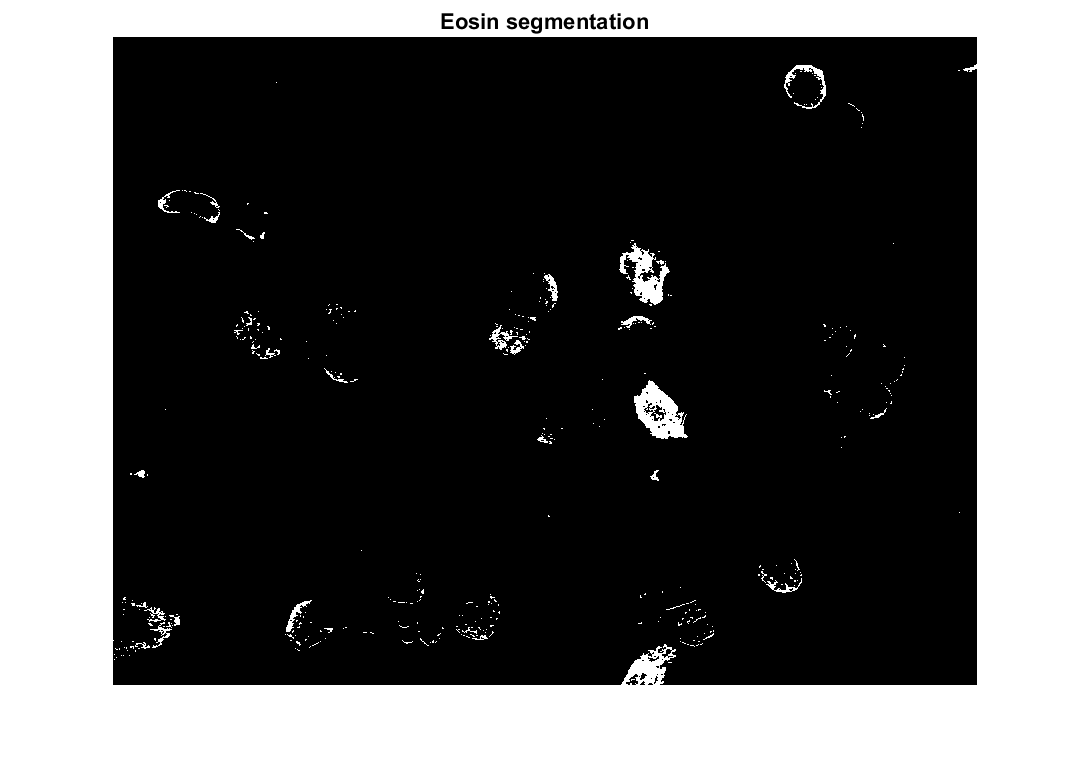

figure;
imshow(uint8(Se-Sh),[]); title('Eosin segmentation');

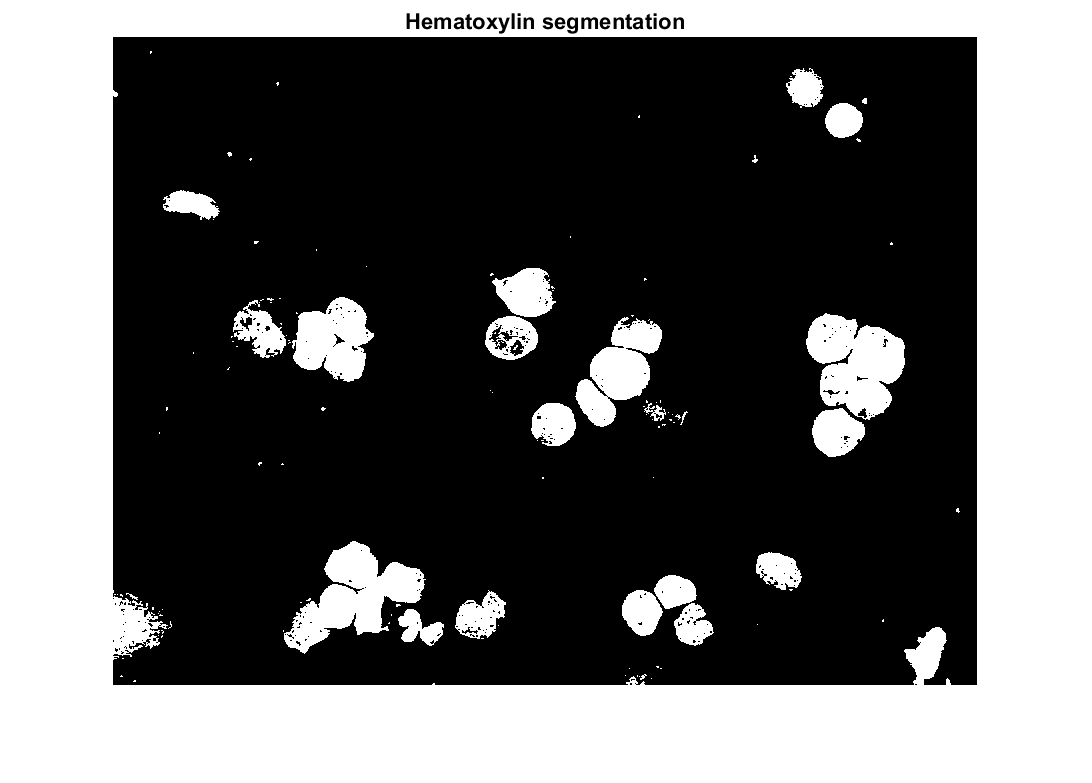

imshow(Sh,[]); title('Hematoxylin segmentation');

function D= deconv(InputImg)

    % set of standard values for optical density (stain vectors)
    % (from research paper named "Quantification of histochemical staining by color deconvolution ")
    He_OD=[0.18;0.20;0.08];
    Eo_OD=[0.01;0.13;0.01];
    DAB_OD=[0.10;0.21;0.29];

    % deconvolution matrix
    decovnMatrix= [He_OD/norm(He_OD) Eo_OD/norm(Eo_OD) DAB_OD/norm(DAB_OD)]';
    decovnMatrix= inv(decovnMatrix) ;

    % convert input image to double
    InputImg = double(InputImg)+1;
    OD = -log(InputImg)+1;   %optical density
    
    % color deconvolution
    D = reshape(OD,[],3) * decovnMatrix;
    D = reshape(D, size(InputImg));
    
    %normalizing the matrix (intensity between 0 and 1) 
	for i=1:size(D,3)
		Pln = D(:,:,i);%         
		D(:,:,i) = (D(:,:,i)-min(Pln(:)))/(max(Pln(:)-min(Pln(:))));
        D(:,:,i) = 1 - D(:,:,i);
    end
    SE=[0,1,0;1,1,1;0,1,0];
    D=imclose(D,SE);
end

function [S,HH,T,L]=segmentation(deconvImg)

HH=imhist(deconvImg);
L=length(HH);
T=round(otsuthresh(HH)*256);
S=1-imbinarize(deconvImg,T/L);

end

